## Root-finding algorithms

Hello biomedical engineers!

Let's find the root of this monstrous equation given to us in class:


$$y = \frac{1}{\sqrt{\text{f}}} + 2.0\log{\left(\frac{\varepsilon}{3.7D} + \frac{2.51}{\text{Re}\sqrt{\text{f}}}\right)}\text{, where the \textit{Reynolds number } Re} = \frac{\rho v D}{\mu}.$$


Note: $\log$ here is the natural logarithm ($\log_e$ or $\ln$), not $\log_{10}$!

First, we need to tell our Symbolic Math Toolbox that these variables are symbols, different from typical variables in programming:

syms f epsilon D rho nu mu

Next, let's define the Reynolds number by putting together some symbols into an equation:

Reynolds_number = rho*nu*D / mu;

That logarithm from earlier is messy. I'm going to abbreviate it as $L$:


$$y = \frac{1}{\sqrt{\text{f}}} + 2.0L\text{, where }L = \log{\left(\frac{\varepsilon}{3.7D} + \frac{2.51}{\text{Re}\sqrt{\text{f}}}\right)}\text{.}$$


L = log(epsilon/(3.7*D) + 2.51/(Reynolds_number*sqrt(f)));

Finally, $y$ can be written neatly:

y = 1/sqrt(f) + 2.0*L;

You can actually ask to see how the Symbolic Math Toolbox interprets all of this, but it likes to rearrange things seemingly to be as complicated as possible:

y

$$y = 2\,\log\left(\frac{10\,\epsilon }{37\,\text{D}}+\frac{251\,\mu }{100\,\text{D}\,\sqrt{f}\,\nu \,\rho }\right)+\frac{1}{\sqrt{f}}$$

Let's stick with $y = \frac{1}{\sqrt{\text{f}}} + 2.0L$.

The Newton-Raphson method makes use of a function's derivative to find its roots.

How do we get a derivative? There are so many variables!

This is where the Symbolic Math Toolbox shines.

Let's say we want to find out which values of epsilon ($\varepsilon \;$) make $y=0$. That means epsilon is the independent variable; the other symbols ($D$, $\rho \;$, etc.) are just constants that can be anything we want.

Since we chose epsilon as the independent variable, let's get the derivative of y with respect to epsilon, written $\frac{\partial y}{\partial \varepsilon }$.

derivative = diff(y, epsilon)

$$derivative = \frac{20}{37\,\text{D}\,\left(\frac{10\,\epsilon }{37\,\text{D}}+\frac{251\,\mu }{100\,\text{D}\,\sqrt{f}\,\nu \,\rho }\right)}$$

That's it! No need to do it by hand.

Now to substitute a value for each constant in $y$ using `subs`:

D =76;
f =0.1;
rho =8.6;
nu =9.01;
mu =40.92;

y_substituted = subs(y)

$$y\_substituted = 2\,\log\left(\frac{5\,\epsilon }{1406}+\frac{256773\,\sqrt{10}}{14722340}\right)+\sqrt{10}$$

derivative_substituted = subs(derivative)

$$derivative\_substituted = \frac{5}{703\,\left(\frac{5\,\epsilon }{1406}+\frac{256773\,\sqrt{10}}{14722340}\right)}$$

Perfect, now $y$ and its derivative have only one variable, epsilon ($\varepsilon$)!

Finally, we need to convert these symbolic equations into MATLAB functions, just like the ones you can define using the `function` keyword or `@(…)`. (For example, $F\left(x\right)=x+5$ is written as "`function y = F(x): y=x+5`" or "F` = @(x) x+5`.")

To convert `y` and `derivative` to MATLAB functions, use `matlabFunction`:

y_function = matlabFunction(y_substituted)

y_function = function_handle with value:
    @(epsilon)log(epsilon.*3.556187766714083e-3+sqrt(1.0e+1).*1.744104537729736e-2).*2.0+sqrt(1.0e+1)


derivative_function = matlabFunction(derivative_substituted)

derivative_function = function_handle with value:
    @(epsilon)(5.0./7.03e+2)./(epsilon.*3.556187766714083e-3+sqrt(1.0e+1).*1.744104537729736e-2)


Notice it says "`@(epsilon)…`," showing that these new MATLAB functions accept `epsilon` as their input (their "argument").

Time to find the root!

close
[root, ea, iter, graph] = newtraph(y_function, derivative_function, 100)

good_approx_error = 1.0000e-04

max_tries = 50

root = 42.3451

ea = 3.4361e-09

iter = 6

graph =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [440 278 560 420]
       Units: 'pixels'

  Show all properties


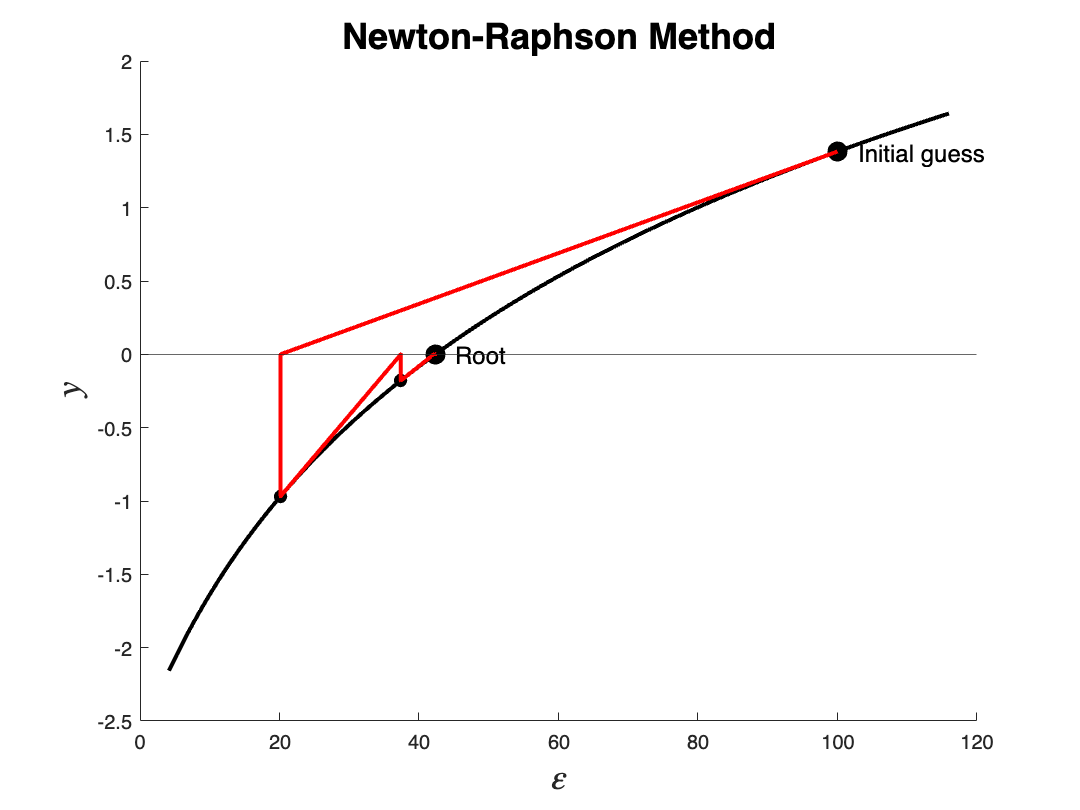


title('Newton-Raphson Method', 'FontSize', 18)
xlabel('$\varepsilon$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)